**Data**

x = [5  10  15  20  25  30  35  40  45  50]

x =      5    10    15    20    25    30    35    40    45    50


y = [17  24  31  33  37  37  40  40  42  41]

y =     17    24    31    33    37    37    40    40    42    41


**Plot data**

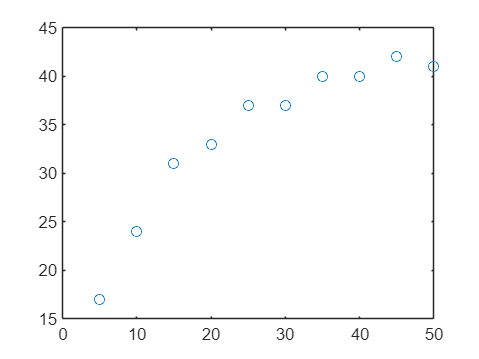

plot(x,y,"o")

**Transform data**

newx=log10(x)

newx =     0.6990    1.0000    1.1761    1.3010    1.3979    1.4771    1.5441    1.6021    1.6532    1.6990


newy = log10(y)

newy =     1.2304    1.3802    1.4914    1.5185    1.5682    1.5682    1.6021    1.6021    1.6232    1.6128


**Perform linear regression & plot dataset + fitted line**

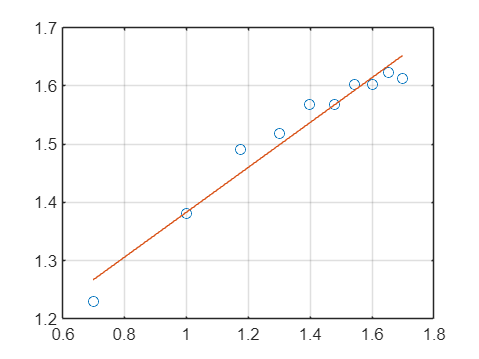

a =     0.3851    0.9980


r2 = 0.9553

[a,r2] = linregr(newx,newy)

**Computer parameters of nonlinear equation from the fitted line**

alpha = 10^(a(2))

alpha = 9.9529

beta = a(1)

beta = 0.3851

**Plot the original data with the best fit nonlinear curve**

xx = 1 : 0.1 : 3

xx =     1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000


yy = alpha * (xx.^beta)

yy =     9.9529   10.3250   10.6768   11.0110   11.3298   11.6348   11.9276   12.2093   12.4810   12.7436   12.9978   13.2443   13.4837   13.7165   13.9432   14.1641   14.3796   14.5901   14.7959   14.9972   15.1942


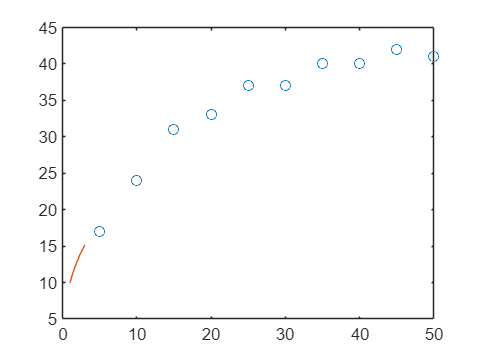


plot(x, y,'o',xx,yy,'-')

**Predict the value of y for the given x**

xtest = 1.5

xtest = 1.5000


predict_y = alpha * (xtest.^beta)

predict_y = 11.6348